Generación de una señal pseudoaleatoria binaria (PRBS).

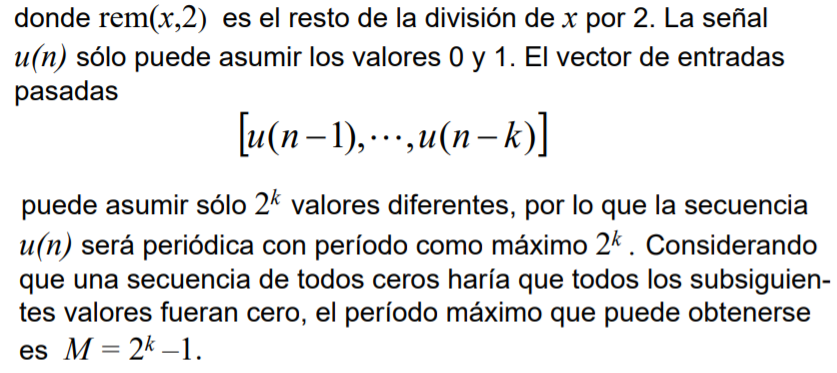

k es el orden.

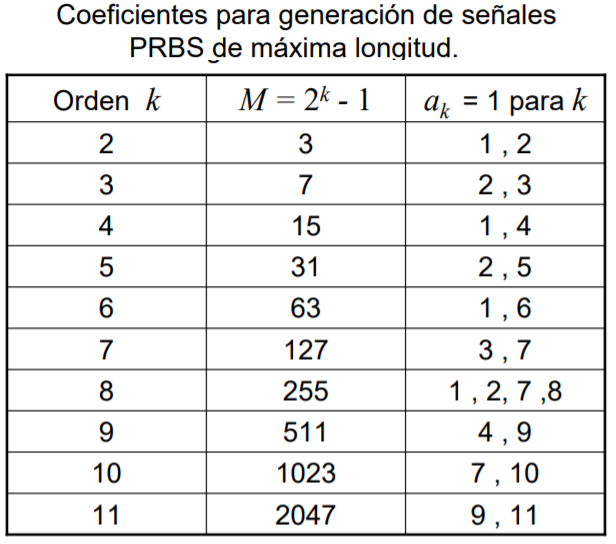

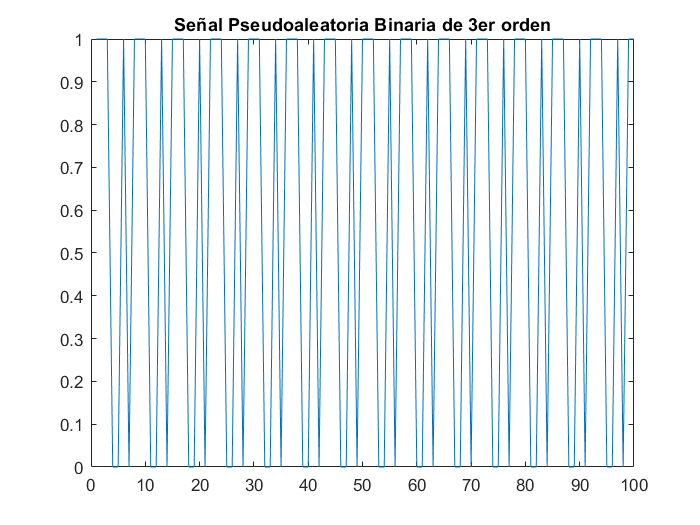


close all

%de 3er orden
a1 = 0; a2=1; a3=1;

u=[1 1 1];
for n=4:100
   u(n)=mod(a1*u(n-1)+a2*u(n-2)+a3*u(n-3),2);
end

plot(u)
title('Señal Pseudoaleatoria Binaria de 3er orden')

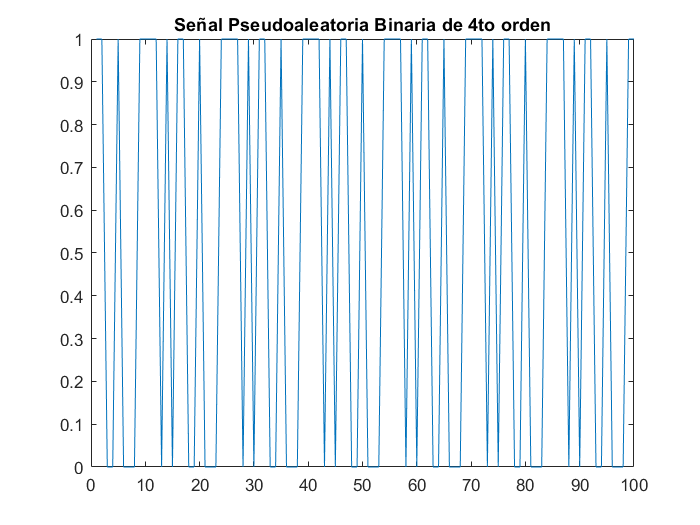


close all

%de 4to orden
a1 = 1; a2=0; a3=0; a4=1;

u=[1 1 0 0];
for n=5:100
   u(n)=mod(a1*u(n-1)+a2*u(n-2)+a3*u(n-3)+a4*u(n-4),2);
end

plot(u)
title('Señal Pseudoaleatoria Binaria de 4to orden')

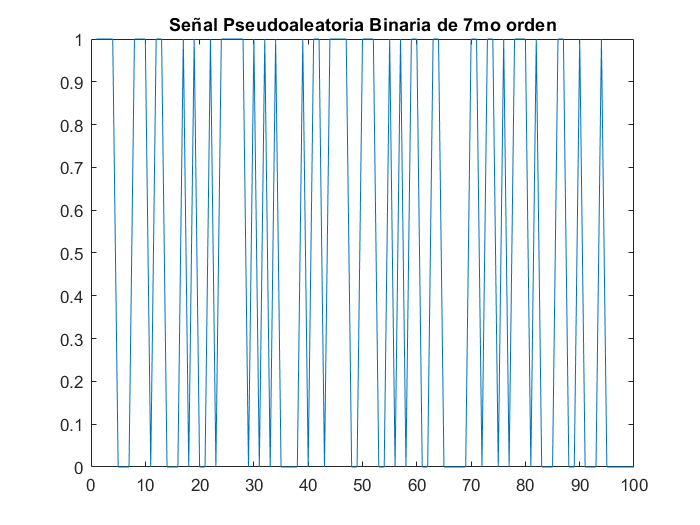


close all

%de 7mo orden
a1 = 0; a2=0; a3=1; a4=0; a5=0; a6=0; a7=1;

u=[1 1 1 1 0 0 0];
for n=8:100
   u(n)=mod(a1*u(n-1)+a2*u(n-2)+a3*u(n-3)+a4*u(n-4)+a5*u(n-5)+a6*u(n-6)+a7*u(n-7),2);
end

plot(u)
title('Señal Pseudoaleatoria Binaria de 7mo orden')

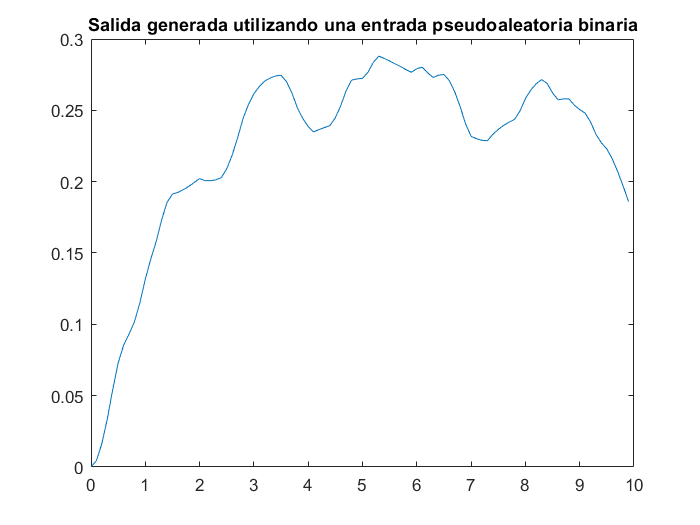


G=tf(1,[1 3 2]);
T=0.1;
t=0:T:((length(u)-1)*T);
y=lsim(G,u,t)';

plot(t,y)
title('Salida generada utilizando una entrada pseudoaleatoria binaria')